# Getting the PSD from data through sample spectrum

## Introduction

In this tutorial you will learn how to estimate the PSD of a random process from a time series through the sample spectrum estimator. The time series is assumed to be a realisation of a zero-mean random process.

The data employed in this tutorial are from folder: '*database/case_01_Mann_1V*', which represents a synthetic time series of the longitudinal component of turbulent wind fluctuation (zero mean), according to the Mann's model. This allows comparison between the estimated PSD and the true PSD corresponding to the model PSD. 

## Tutorial

First of all, add mVARbox to path, set the tutorial parameters and load the data.

setmVARboxPath

mVARbox path has been added to MATLAB path



clear
clc
close all


%%% Parameters
N_f             = 100;      % number of elements of the frequency vector


%%% Plot parameters
font_size       = 18;
figure_position = [0 0 800 400];


%%% Load data
load case_01_Mann_1V.mat

Have a look at the time series considered. 

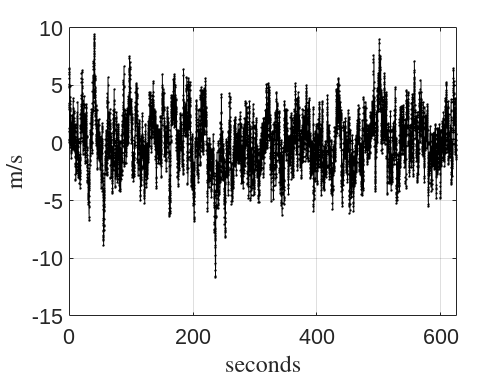

figure

x = data_Mann.x_values;
y = data_Mann.y_values;
plot(x,y,'.-k')
grid on
xlabel('seconds','Interpreter','latex')
ylabel('m/s','Interpreter','latex')

set(gca,'fontsize',font_size)

Note the sampling time and the time span of the data. They are useful to define the maximum frequency, $f_{max}$, and the minimum frequency, $f_{min}$. The frequency vector to evaluate the sample spectrum will be defined within this frequency range.

delta_t     = data_Mann.x_parameters.delta_x;   % seconds
t_sim       = delta_t*data_Mann.x_parameters.N; % seconds

f_max       = 1/(2*delta_t);
f_min       = 1/t_sim;

f_vector    = linspace(f_min,f_max,N_f);

Initialise an S object with the frequency vector where the sample spectrum will be evaluated. 

S0 = initialise_S('x_values', f_vector);

Compute the sample spectrum.

[ S_sample ] = get_S_sample_spectrum(data_Mann, S0);

Plot the obtained sample spectrum together with the true spectrum.

figure

x = S_sample.x_values;
y = S_sample.y_values;
plot(x,y,'.-')
hold on
x = S_Mann.x_values;
y = S_Mann.y_values;
plot(x,y,'.-')
legend({'$S_{sample}$','$S_{Mann}$'},'Interpreter','latex','Location','bestoutside')
grid on
xlabel('$f$ [Hz]','Interpreter','latex')

set(gca,'fontsize',font_size)

Sometimes the spectrum is better represented in x-log scale.

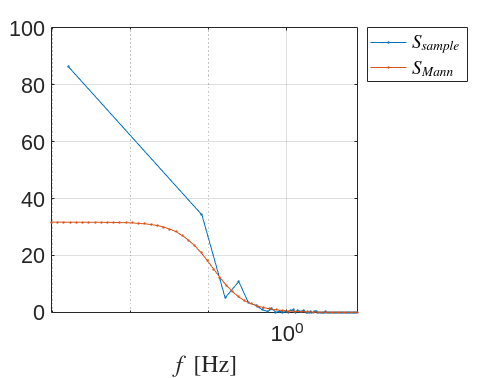

set(gca,'Xscale','log')

The problem of using a linearly spaced `f_vector` and the use of the x-log scale is that the sprectrum shows irregular resolution for different frequencies. This can be addressed by defining a logarithmically spaced vector `f_vector`.

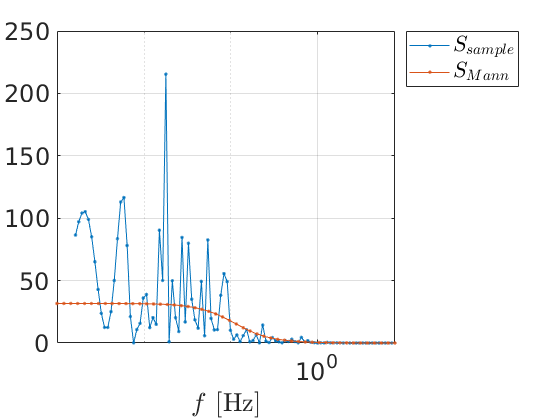

f_vector_log        = logspace(log10(f_min),log10(f_max),N_f);
S0_log              = initialise_S('x_values', f_vector_log);
[ S_sample_log ]    = get_S_sample_spectrum(data_Mann, S0_log);

figure

x = S_sample_log.x_values;
y = S_sample_log.y_values;
plot(x,y,'.-')
hold on
x = S_Mann.x_values;
y = S_Mann.y_values;
plot(x,y,'.-')
legend({'$S_{sample}$','$S_{Mann}$'},'Interpreter','latex','Location','bestoutside')
grid on
xlabel('$f$ [Hz]','Interpreter','latex')

set(gca,'Xscale','log')
set(gca,'fontsize',font_size)

For the case of wind turbulence, it is more common to represent the product $f \cdot S$, in both log-linear and log-log scales.

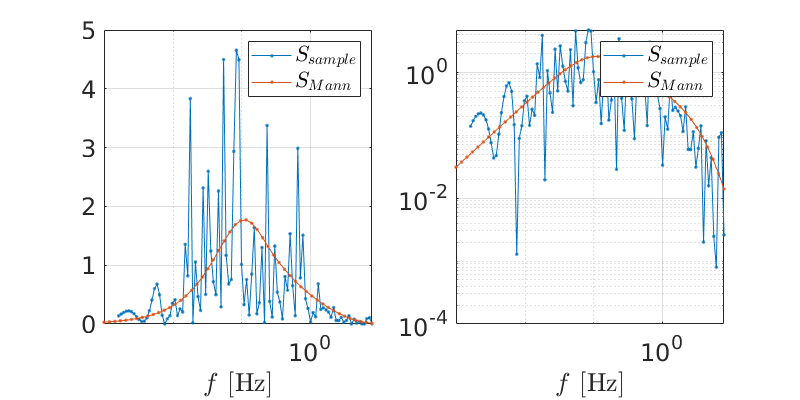

figure

subplot(1,2,1)
x = S_sample_log.x_values;
y = S_sample_log.y_values;
plot(x,x.*y,'.-')
hold on
x = S_Mann.x_values;
y = S_Mann.y_values;
plot(x,x.*y,'.-')
legend({'$S_{sample}$','$S_{Mann}$'},'Interpreter','latex')
grid on
xlabel('$f$ [Hz]','Interpreter','latex')
set(gca,'Xscale','log')
set(gca,'fontsize',font_size)

subplot(1,2,2)
x = S_sample_log.x_values;
y = S_sample_log.y_values;
plot(x,x.*y,'.-')
hold on
x = S_Mann.x_values;
y = S_Mann.y_values;
plot(x,x.*y,'.-')
legend({'$S_{sample}$','$S_{Mann}$'},'Interpreter','latex')
grid on
xlabel('$f$ [Hz]','Interpreter','latex')

set(gca,'Xscale','log')
set(gca,'Yscale','log')
set(gca,'fontsize',font_size)

set(gcf,'position',figure_position)

## Remarks

- Note that the PSD is a continuous function of the frequency, and it can be evaluated at any frequency value. 

- However, the PSD estimated from a discrete time series is periodic for frequencies higher thant $f_{max} $. You can check it just by changing `f_vector` accordingly. 

- Also, the estimated spectrum for frequencies below $f_{min}$ are likely to be unaccurate because the time simulation of the data, `t_sim`, is not long enough to capture such small frequencies.

- Since the sample spectrum is based on the DTFT and the DTFT is a smooth function of the frequency, the spectrum is also a smooth function. The seemingly spiking behaviour in a plot can be avoided just by increasing the number of points in the frequency vector (`N_f`).

- If the data object is multivariate, you can select the time series (the column) employed to obtain the sample spectrum through the input parameter `k`, see function get_S_sample_spectrum for details. You can obtain the sample spectrum of all the time series at once by selecting `k=0`, or just not indicating any value for k (`k=0` is the default value).